Кабанов Степан. 109 группа.

Домашнее задание по теме "Нахождение корня функции одной переменной".

Номер 1.

Найти корень уравнения 

x^2 - a = 0

a = 5;
func = @(x) x.^2 - a;
rt1 = fzero(func, -1);
rt2 = fzero(func, 1);
rt1, rt2

Номер 2.

Найти корень уравнения 

x^2 + 2x - 1 - sin(x) = 0

func = @(x) x.^2 + 2.*x - 1 - sin(x);
rt1 = fzero(func, -2)
rt2 = fzero(func, 2)

Номер 3.

Найти корни уравнений (Любые три на выбор)

а) sin(exp(x)) = 0 на промежутке [-3, 3]

a = 2; % Начальное приближение
func = @(x) sin(exp(x));
rt = fzero(func, a);
rt

с) xsinx - cosx = 0 на промежутке [0, 4pi]

a = pi; %Начальное приближение
func = @(x) x.*sin(x) - x.*cos(x);
rt = fzero(func, a);
rt

e) 5*exp(-0.1x)*sin(x) - 0.1x = 0 на промежутке [-2pi, 6pi]

a = 4*pi;
func = @(x) 5.*exp(-0.1.*x).*sin(x) - 0.1.*x;
rt = fzero(func, a);
rt

Номер 4.

a = 0;
func = @(x) x.^2 + 1;
rt_fzero = fzero(func, a)

syms x;
eqn = x^2 + 1 == 0;
rt_solve = solve(eqn)

Ответ: Функция fzero ищет корни в вещественном пространстве численными методами и возвращает только один корень.

Функция solve аналитически решает уравнение находя все корни.

Номер 5.

func = @(x) cos(x) - exp(0.001 + x.^2);
X = -50:0.001:50;
Y = func(X);
plot(X,Y)
fzero(func, 0)
syms x;
eqn = cos(x) - exp(0.001 + x^2) == 0;
solve(eqn)

"Численные методы решения уравнений"

Номер 1.

Найти корни уравнения на промежутке методом Ньютона и методом деления интервала пополам.

Опишем метод Ньютона и метод деления интервалов пополам в отдельных функциях.

newton.m - решение методом Ньютона

interval.m - решение методом интервалов

a) Ньютон

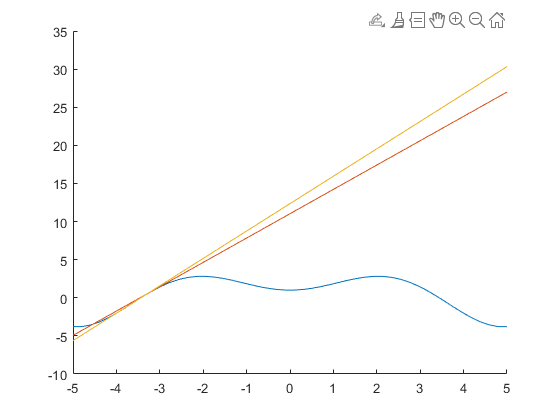

x1 = -3.4369

clear;
func = @(x) 1 + x.*sin(x);
newton(func, -5, 5);

а) Интервалы

interval(func, -5, 5);

b)  sinx/x

Ньютон

func = @(x) sin(x)./x;
newton(func, 0, 14);

b) Интервалы

interval(func, 0, 14);

с) Ньютон

func = @(x) 1 + (1 + sin(x) - cos(x)).^2 - (sin(2.*x) - cos(2.*x) - 0.2).^2;
newton(func, 0, 6);

c) Интервалы

interval(func, 0, 6);